# Macm 203 Assignment 5

April Nguyen

## Preamble

Here we consider some introductory image processing techniques.

## Questions.

## Part A: Construct a Vignette Image

Flamingos are fascinating creatures often found in vibrant and picturesque settings. In this question, you will explore the concept of vignetting and construct a vignette image of the built-in flamingos.jpg image using MATLAB. Before proceeding, let's first understand what a vignette image is:

*A vignette image is an image with an artistic effect where the brightness decreases gradually from the centre towards the edges, creating a subtle darkening or fading effect. This technique draws focus to the centre of the image, enhancing its visual appeal and depth.*

Task:

- Load the built-in flamingos.jpg image into MATLAB

- Implement your own MATLAB algorithm to construct a vignette image from the original image. Apply vectorization techniques wherever applicable to optimize your code's efficiency.

- Display both the original and vignette images side by side for comparison.

In your live script, include your MATLAB code along with a brief explanation of your approach and any observations made during the process.

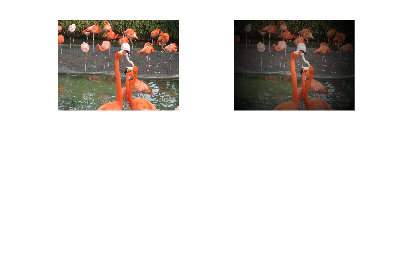

clear,clf;
% load flamingos.jpg into MATLAB
I = imread('flamingos.jpg');
%imshow(I)
%whos I
% implement algorithm to construct image -> vignette image
% decrease brightness by decreasing the values
% borders should be black, center should stay the same brightness
% smooth transition between center and borders
% change the brightness based on the distance from the center
[rows, cols, colours] = size(I);

centerx = cols/2;
centery = rows/2;

% calculate distance from center to corner (1,1)
totalDistance = sqrt( centerx^2 + centery^2 );

[X,Y] = meshgrid(1:cols,1:rows);
%calculate distance from center to any point (x,y)
gradient = sqrt((X-cols/2).^2 + (Y-rows/2).^2);

gradientNorm = 1 - gradient./totalDistance;

Ivign = double(I);
Ivign(:,:,1) = Ivign(:,:,1).*gradientNorm;
Ivign(:,:,2) = Ivign(:,:,2).*gradientNorm;
Ivign(:,:,3) = Ivign(:,:,3).*gradientNorm;

Ivign = uint8(Ivign);
%imshow(Ivign);
%tiled = imtile({I,Ivign});
%imshow(tiled);

subplot(2,2,1)
imshow(I)
subplot(2,2,2)
imshow(Ivign)

## Part B: Thresholding

In this question, you will apply thresholding techniques to detect objects and backgrounds in images.

From http://syllabus.cs.manchester.ac.uk/ugt/2020/COMP27112/doc/matlab.pdf :

*Thresholding is a simple method of differentiating between an ****object**** and the ****background****, which works provided they are of different intensities. A threshold value is defined. Intensities greater that this are set to one value, intensities less than to another (1 or max, and 0 or min are often used). Whilst a threshold can be decided manually, it is better to use the image data to compute one. Gonzalez and Woods suggested this method:*

*i)    Choose a threshold arbitrarily*

*ii)    Threshold the image using it*

*iii)    Compute the mean grey value of the pixels with intensities above and below the threshold, and then compute the average of these two values.*

*iv)    Use the new value to re-threshold the original image*

*v)    Repeat steps iii) and iv) until the threshold changes by an insignificant amount.*

Task:

- Load the built-in pepper.png image into MATLAB and convert it into grayscale using rgb2gray().

- Implement a MATLAB algorithm to apply Gonzalez and Woods thresholding to your grayscale image. Apply vectorization techniques wherever applicable to optimize your code's efficiency.

- What objects are found? Display only the found objects. This can be accomplished by setting the rest of the image to black.

- Find an image that seems well-suited to Gonzalez and Woods thresholding and Repeat Tasks 1-3.

- For both pepper.png and your image, visually evaluate your results.

In your live script, include your MATLAB code. Document your observations and any challenged encountered in getting your anticipated results. Critically assess the Gonzalez and Woods thresholding algorithm.

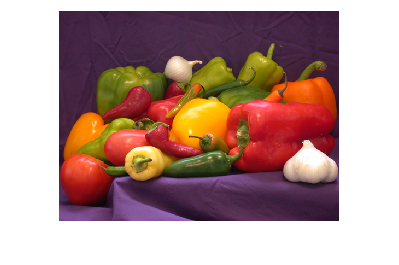

clear, clf;
% 1. Load the built-in pepper.png image into MATLAB and convert it into
% grayscale using rgb2gray()
I = imread('peppers.png');
imshow(I)

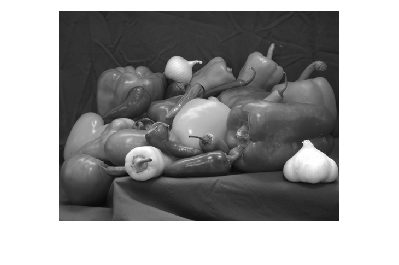

I = rgb2gray(I);
imshow(I)

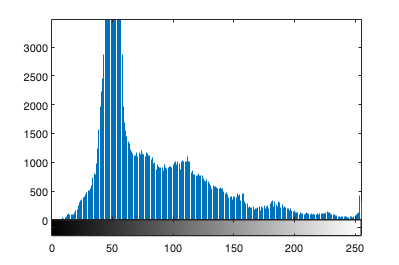

imhist(I)

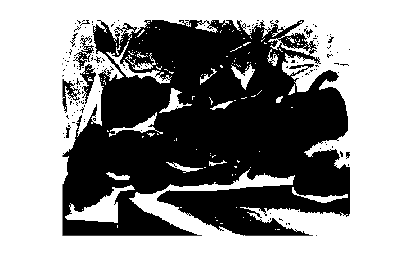

I = double(I);
% 2. Implement a MATLAB algorithm to apply Gonzales and Woods thresholding
% to your grayscale image. Apply vectorization techniques wherever
% applicable to optimize your code's efficiency.
% i. Choose a threshold arbitrarily
T = 50;
% ii. Threshold the image using it
% if below threshold make it 1 (white), background
% if at or above threshold make it 0 (black), object
Ithresh = I < T; 
imshow(Ithresh);

% iii. Compute the mean grey value of the pixels with intensities above and
% below the threshold, and then compute the average of these two values.
imageSize = size(I);
height = imageSize(1);
width = imageSize(2);
belowT = double(0);
atAboveT = double(0);
Ithresh = im2double(Ithresh);
countBelowT = sum(sum(Ithresh));
countAtAboveT = height*width;
countAtAboveT = countAtAboveT - countBelowT;
%a = I(1,1)
%whos a
%b = I(248,14)
for i=1:height
    for j=1:width
        if (Ithresh(i,j) == 1)
            belowT = belowT + I(i,j);
        else
            atAboveT = atAboveT + I(i,j);
        end
    end
end
meanBelowT = belowT / countBelowT;
meanAtAboveT = atAboveT / countAtAboveT;
average = (meanBelowT + meanAtAboveT)/2;
% iv. Use the new value to re-threshold the original image
T = average

T = 69.2982

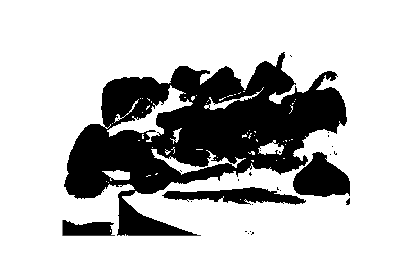


Ithresh = I < T;
imshow(Ithresh)


belowT = double(0);
atAboveT = double(0);
Ithresh = im2double(Ithresh);
countBelowT = sum(sum(Ithresh));
countAtAboveT = height*width;
countAtAboveT = countAtAboveT - countBelowT;
for i=1:height
    for j=1:width
        if (Ithresh(i,j) == 1)
            belowT = belowT + I(i,j);
        else
            atAboveT = atAboveT + I(i,j);
        end
    end
end
meanBelowT = belowT / countBelowT;
meanAtAboveT = atAboveT / countAtAboveT;
average = (meanBelowT + meanAtAboveT)/2;
T = average

T = 86.0414

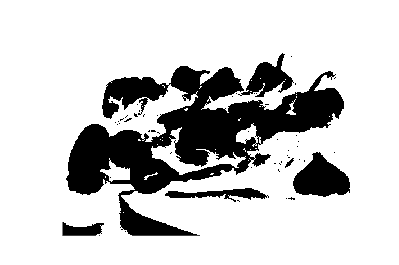

Ithresh = I < T;
imshow(Ithresh);


belowT = double(0);
atAboveT = double(0);
Ithresh = im2double(Ithresh);
countBelowT = sum(sum(Ithresh));
countAtAboveT = height*width;
countAtAboveT = countAtAboveT - countBelowT;
for i=1:height
    for j=1:width
        if (Ithresh(i,j) == 1)
            belowT = belowT + I(i,j);
        else
            atAboveT = atAboveT + I(i,j);
        end
    end
end
meanBelowT = belowT / countBelowT;
meanAtAboveT = atAboveT / countAtAboveT;
average = (meanBelowT + meanAtAboveT)/2;
T = average

T = 94.2949

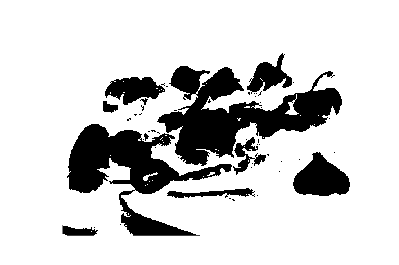

Ithresh = I < T;
imshow(Ithresh);


belowT = double(0);
atAboveT = double(0);
Ithresh = im2double(Ithresh);
countBelowT = sum(sum(Ithresh));
countAtAboveT = height*width;
countAtAboveT = countAtAboveT - countBelowT;
for i=1:height
    for j=1:width
        if (Ithresh(i,j) == 1)
            belowT = belowT + I(i,j);
        else
            atAboveT = atAboveT + I(i,j);
        end
    end
end
meanBelowT = belowT / countBelowT;
meanAtAboveT = atAboveT / countAtAboveT;
average = (meanBelowT + meanAtAboveT)/2;
T = average

T = 98.0012

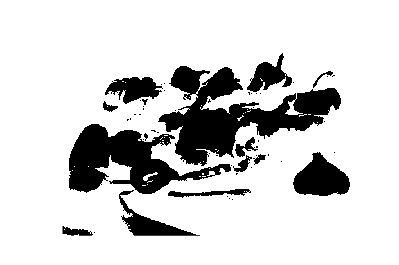

Ithresh = I < T;
imshow(Ithresh);


belowT = double(0);
atAboveT = double(0);
Ithresh = im2double(Ithresh);
countBelowT = sum(sum(Ithresh));
countAtAboveT = height*width;
countAtAboveT = countAtAboveT - countBelowT;
for i=1:height
    for j=1:width
        if (Ithresh(i,j) == 1)
            belowT = belowT + I(i,j);
        else
            atAboveT = atAboveT + I(i,j);
        end
    end
end
meanBelowT = belowT / countBelowT;
meanAtAboveT = atAboveT / countAtAboveT;
average = (meanBelowT + meanAtAboveT)/2;
T = average

T = 99.9415

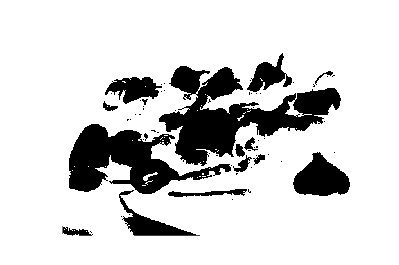

Ithresh = I < T;
imshow(Ithresh);


belowT = double(0);
atAboveT = double(0);
Ithresh = im2double(Ithresh);
countBelowT = sum(sum(Ithresh));
countAtAboveT = height*width;
countAtAboveT = countAtAboveT - countBelowT;
for i=1:height
    for j=1:width
        if (Ithresh(i,j) == 1)
            belowT = belowT + I(i,j);
        else
            atAboveT = atAboveT + I(i,j);
        end
    end
end
meanBelowT = belowT / countBelowT;
meanAtAboveT = atAboveT / countAtAboveT;
average = (meanBelowT + meanAtAboveT)/2;
T = average

T = 100.4371

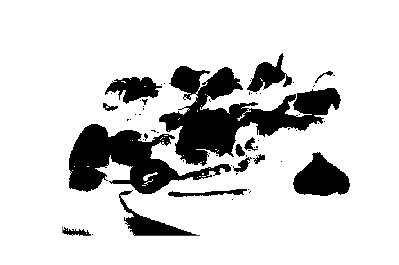

Ithresh = I < T;
imshow(Ithresh);

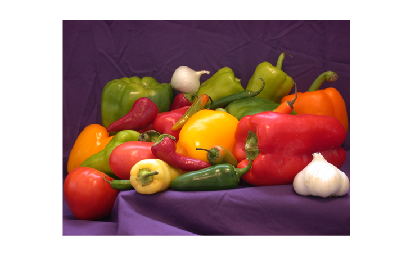


Inew = imread('peppers.png');
imshow(Inew);

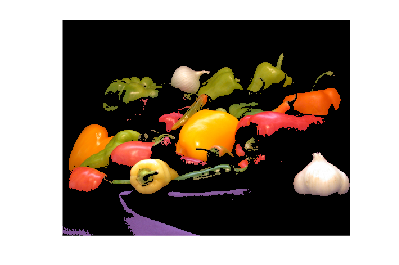

%Inew(1:100,1:100,1)=0;
%Inew = double(Inew);
for i=1:height
    for j=1:width
        if (Ithresh(i,j) == 1)
            Inew(i,j,1) = 0;
            Inew(i,j,2) = 0;
            Inew(i,j,3) = 0;
        end
    end
end
imshow(Inew);

3. What objects are found? Display only the found objects. This can be accomplished by setting the rest of the image to black.

    The found objects are the peppers. The background has been blacked out to display the found pepper objects.

4. Find an image that seems well-suited to Gonzalez and Woods thresholding and repeat Tasks 1-3.

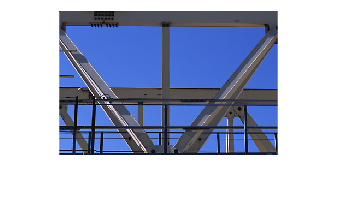

clc,clf;

I = imread('gantrycrane.png');
imshow(I);

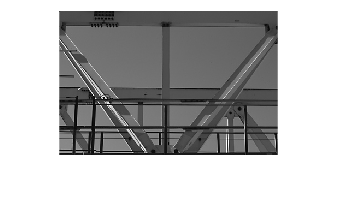

I = rgb2gray(I);
imshow(I);

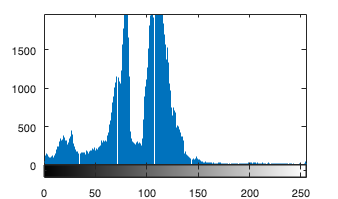

imhist(I);

I = double(I);
T = 50;
Ithresh = I < T; %set to 1 if I < T (darker than threshold)
%imshow(Ithresh);

imageSize = size(I);
height = imageSize(1);
width = imageSize(2);

belowT = double(0);
atAboveT = double(0);
Ithresh = im2double(Ithresh);
countBelowT = sum(sum(Ithresh));
countAtAboveT = height*width;
countAtAboveT = countAtAboveT - countBelowT;
for i=1:height
    for j=1:width
        if (Ithresh(i,j) == 1)
            belowT = belowT + I(i,j);
        else
            atAboveT = atAboveT + I(i,j);
        end
    end
end
meanBelowT = belowT / countBelowT;
meanAtAboveT = atAboveT / countAtAboveT;
average = (meanBelowT + meanAtAboveT)/2;

T = average

T = 63.1644


Ithresh = I < T;
%imshow(Ithresh)

belowT = double(0);
atAboveT = double(0);
Ithresh = im2double(Ithresh);
countBelowT = sum(sum(Ithresh));
countAtAboveT = height*width;
countAtAboveT = countAtAboveT - countBelowT;
for i=1:height
    for j=1:width
        if (Ithresh(i,j) == 1)
            belowT = belowT + I(i,j);
        else
            atAboveT = atAboveT + I(i,j);
        end
    end
end
meanBelowT = belowT / countBelowT;
meanAtAboveT = atAboveT / countAtAboveT;
average = (meanBelowT + meanAtAboveT)/2;

T = average

T = 68.4982


Ithresh = I < T;
%imshow(Ithresh)

belowT = double(0);
atAboveT = double(0);
Ithresh = im2double(Ithresh);
countBelowT = sum(sum(Ithresh));
countAtAboveT = height*width;
countAtAboveT = countAtAboveT - countBelowT;
for i=1:height
    for j=1:width
        if (Ithresh(i,j) == 1)
            belowT = belowT + I(i,j);
        else
            atAboveT = atAboveT + I(i,j);
        end
    end
end
meanBelowT = belowT / countBelowT;
meanAtAboveT = atAboveT / countAtAboveT;
average = (meanBelowT + meanAtAboveT)/2;

T = average

T = 72.3497


Ithresh = I < T;
%imshow(Ithresh)

belowT = double(0);
atAboveT = double(0);
Ithresh = im2double(Ithresh);
countBelowT = sum(sum(Ithresh));
countAtAboveT = height*width;
countAtAboveT = countAtAboveT - countBelowT;
for i=1:height
    for j=1:width
        if (Ithresh(i,j) == 1)
            belowT = belowT + I(i,j);
        else
            atAboveT = atAboveT + I(i,j);
        end
    end
end
meanBelowT = belowT / countBelowT;
meanAtAboveT = atAboveT / countAtAboveT;
average = (meanBelowT + meanAtAboveT)/2;

T = average

T = 76.1943


Ithresh = I < T;
%imshow(Ithresh)

belowT = double(0);
atAboveT = double(0);
Ithresh = im2double(Ithresh);
countBelowT = sum(sum(Ithresh));
countAtAboveT = height*width;
countAtAboveT = countAtAboveT - countBelowT;
for i=1:height
    for j=1:width
        if (Ithresh(i,j) == 1)
            belowT = belowT + I(i,j);
        else
            atAboveT = atAboveT + I(i,j);
        end
    end
end
meanBelowT = belowT / countBelowT;
meanAtAboveT = atAboveT / countAtAboveT;
average = (meanBelowT + meanAtAboveT)/2;

T = average

T = 79.7532

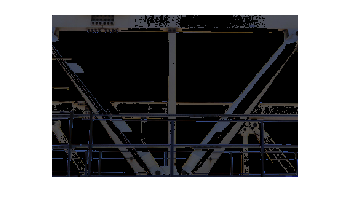


Ithresh = I < T;
%imshow(Ithresh)

Inew = imread('gantrycrane.png');
for i=1:height
    for j=1:width
        if (Ithresh(i,j) == 0)
            Inew(i,j,1) = 0;
            Inew(i,j,2) = 0;
            Inew(i,j,3) = 0;
        end
    end
end
imshow(Inew);

For the image gantrycrane.jpg, there is a clear difference between the background and object, so the thresholding works quite well to find the object. It is a bit difficult to see since the object is not very bright. However, the Gonzalez and Woods thresholding is not that great for images with similar intensities between the background and object.